# **Método de Euler**

### Método numerico para ecuaciones de la forma $\frac{dy}{dx}=f(x,y)$ con condición inicial $y(x_0)=y_0$

Dada la condición inicial  $y(x_0)=y_0$ y el tamaño de paso $\Delta x$, calculamos el punto $(x_{n+1},y_{n+1})$ a partir del punto precedente $(x_n,y_n)$ con los siguientes pasos:

- Usamos la ecuación diferencial para determinar la pendiente $f(x_n,y_n)$

- Calculamos el siguiente punto $(x_{n+1},y_{n+1})$ mediante las fórmulas:


$$x_{n+1}=x_n+\Delta x$$



$$y_{n+1}=y_n+f(x_n,y_n)\Delta x$$



$$n=0,1,2,...$$


### EJEMPLO: Modelo de caida libre

Un objeto en caida libre se ve afectado escencialmente por dos fuerzas, la gravitacional $F_g=mg$ que provoca la caida del cuerpo, donde $$m$$ es la masa del cuerpo y $$g$$ es la acelaración de la gravedad en el punto de caida. La caida tambien se ve afecta por la fuerza de fricción $$F_f=-cv$$ que "frena" al cuerpo durante esta caida, donde $$c$
$es el coeficiente de arraste entendido como un factor de fricción y $$v$$ la velocidad de caida para el tiempo $$t$$. Debido a que el cuerpo se mueve podemos escribir la ecuación de movimiento como $$ma=F_g+F_f$$. Esta ecuación puede escirbirse como $$m\frac{dv}{dt}=mg-cv$$ rescrita como $$\frac{dv}{dt}=g-\frac{c}{m}v$$.

Para calcular una aproximación para todo punto $$t$$ de este modelo de caida libre a partir del método de Euler identificamos que la función $$f(t,v)=f(v)=g-\frac{c}{m}v$$. Por lo tanto esta ecuación diferencial cumple ser con una ecuación diferencial autonoma y se puede discretizar a partir del los pasos descritos en el método de Euler.

Consideremos la condición inicial $$v(t_0)=v_0$$, es decir al tiempo inicial $$t_0$$ la velocidad inicial es $$v_0$$. La función discretizada estaría dada por le ecuación $$$v(t_{n+1})=v(t_n)+\left[g-\frac{c}{m}v(t_n)\right]\Delta t$$$

### Solución del ejercicio

Para resolver este problema numéricamente consideremos inicialmente $$\Delta t=1$$, $$n=10$$ pasos lo que implica que el tiempo máximo en nuestro modelo es $$t_{max}=10$$, la condición inicial $$v(0)=0$$, y los parámetros $$c=12$$, $$m=68$$ y $$g=9.81$$.

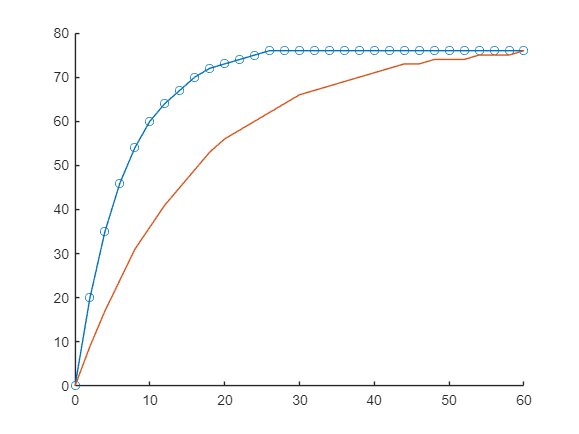

%% Progama para simular la caida libre
%% Arnaldo Hernández Cardona
%% 10/02/2025
clc, clear, close all
%Definiciones de parámetros
g=9.81; %aceleración de la gravedad promedio m/s^2
c=12.7;  %coeficiente de arrastre kg/s
m=100;  %masa en kg
dt=2;   %intervalo de tiempo en s
t_max=60; %tiempo máximo de la simulación en s

%Condiciones inicales
t= 0 : dt : t_max;
t(1)=0;
v=zeros( 1 , length(t) );
v(1)=0;

%cálculo de la velocidad
for i = 1 : length(t)-1
   
    v(i+1) =round((g - (c/m * v(i))) * dt + v(i),0);

end

hold on
plot(t,v, '-o')

%%Solución analítica
v_ex=zeros( 1 , length(t));
v_ex(1)=0;
e_v(1)=0;
for i = 1 : length(t)-1

    v_ex(i+1) = round(g*m/c * ( 1 - exp(-c/m*i)),0);

    e_v(i+1)=( v_ex(i+1) - v(i+1) ) / v_ex(i+1);

end
plot(t,v_ex)

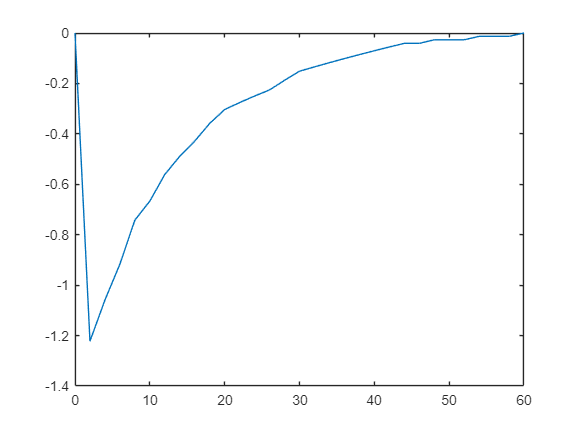


figure
plot(t,e_v)